# Simulation: Linear Acceleration Ramp

## Define motor parameters

global TIMER_RES acc vmax alpha stepsPerRevolution;

TIMER_RES = 1000000;

acc = 100;        % U min-1 s-1
vmax = 200;      % U min-1
stepsPerRevolution = 200;

## Convert parameters into SI units

acc = umin_to_radsec(acc);          % rad s-2
vmax = umin_to_radsec(vmax);         % rad s-1
alpha = 2*pi/stepsPerRevolution;    % angle per step

## Global variables

global n c ds dir c0 pos;

pos = 0;            % position of the stepper
ds = 2000;         % number of steps to go
n = 0;              % initial step number on acc ramp
c = 0;              % current count
dir = 0;              % direction
c0 = 0.676 * TIMER_RES * sqrt(2*alpha/acc);
disp(acc);

   10.4720



disp(alpha);

    0.0314



disp(c0);

   5.2363e+04




%%%%%%% Change here to set a speed different from zero at start:
init_v = 11.4854;
n = 200; % corresponding count
dir = 1;

% don't change below
c = velocity_to_count(init_v);

totT = 0;
ts = [0];
vs = [radsec_to_umin(init_v)];
steps = [0];

## Processing acceleration and deceleration

while ds ~= 0 || n ~= 0
    
    %%%%%%%%%%%%%% Decision Making
    if n == 0
        if ds > 0
            dir = 1;        % cw
            accelerate();
        else
            dir = -1;       % ccw
            accelerate();
        end
    elseif (dir > 0 && ds >= 0) || (dir<0 &&ds <= 0)
        % direction and ds match
        if abs(ds) > n
            accelerate();
        else
            brake();
        end
    else % direction and ds opposed
        brake();        
    end
    %%%%%%%%%%%%%% Stepping
    step();
    totT = totT + c;
    ts = [ts, totT];
    vs = [vs, dir*radsec_to_umin(count_to_velocity(c))];
    steps = [steps, pos];
%     if n == 200 % print a velocity for a certain step on the ramp
%         disp(count_to_velocity(c))
%     end 
end

## Plot the outcome

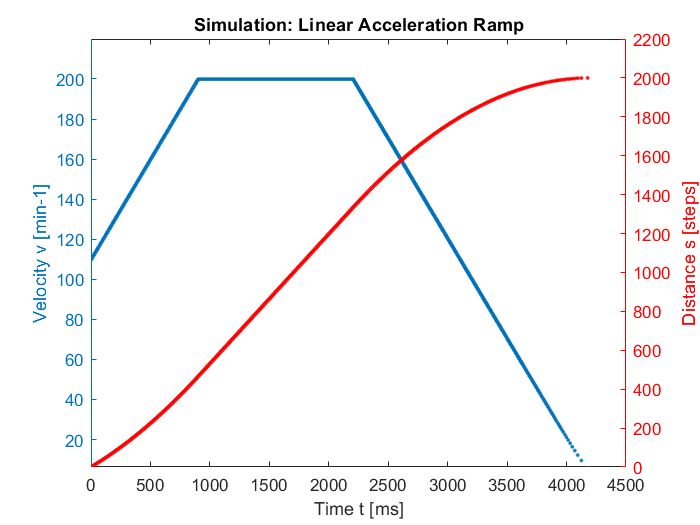

% Distance on the right y-axis
yyaxis right
ax = gca;
ax.YColor = 'r';
plot(ts/1000, steps, '.', 'Color', 'r');
ylabel("Distance s [steps]");
ylim([0, max(steps)*1.1]);
hold on;

% Speed on the left y-axis
yyaxis left
plot(ts/1000, vs, '.');
ylim([min(vs)*1.1, max(vs)*1.1])
ylabel("Velocity v [min-1]");

title("Simulation: Linear Acceleration Ramp");
xlabel("Time t [ms]");
hold off;

## Simulation functions

function result = umin_to_radsec(umin)
    result = umin * 2 * pi / 60;
end

function result = radsec_to_umin(radsec)
    result = radsec*60 / 2 / pi;
end

function result = count_to_velocity(count)
    global alpha
    global TIMER_RES
    if count == 0
        result = 0;
    else
        result = alpha * TIMER_RES / count;
    end
    
end

function result = velocity_to_count(velocity)
    global alpha
    global TIMER_RES
    if velocity == 0
        result = 0;
    else
        result = alpha * TIMER_RES / velocity;
    end;    
end

function step()
    global dir ds pos;
    if dir > 0
        ds = ds - 1;
        pos = pos +1;
    elseif dir < 0
        ds = ds + 1;
        pos = pos-1;
    end
end

function accelerate()
    global c n c0 vmax
    if c == 0
        c = c0;
        n = 0;
    else
        n = n+1;
        %  Clean, but inefficient on microprocessor
%         c = c -2*c /(4*n+1);
%         if c < velocity_to_count(vmax)
%             brake();
%         end
        % More efficient alternative
        newc = c - 2*c /(4*n+1);
        if newc >= velocity_to_count(vmax)
            c = newc;
        else
            % don't change velocity otherwise
            n = n-1;
        end
    end
end

function brake()
    global c n
    if n > 0
        c = c - 2*c/(-4*n+1);
        n = n-1;
    else
        c = 0;
    end
end